## Blood pressure 

### Tasks

1. Calculate the mean arterial pressure (MAP) as measured blood pressure (BP) data from the rat as a response to BP for L-name administration. Filter the obtained course using a moving average filter. Display all three signals in a common graph (KT, MAP, MAPfilt), each in a different color.

2. Identify the dynamic MAPfilt response model to the L-name administration in the form


$$S_{L-name}(s)=\frac{b_2s^2+b_1s+b_0}
{a_3s^3+a_2s^2+a_1s+1$$


Also show the model response in the chart above.

3. Calculate the course of the heart rate from the course of blood pressure and display it in the next graph. Identify a dynamic heart rate response (TF) model. Compare the response of the model with the actual course of TF.

#### Initialize WorkSpace

clc; clear all; close all; addpath('..')

### 1. Load data

load("data_KT1.mat")

#### Plot raw data

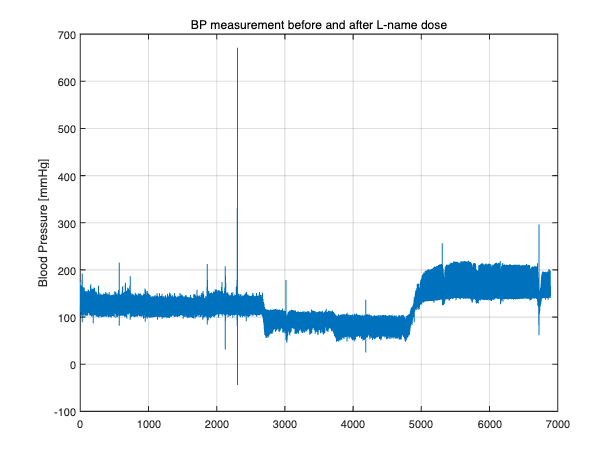

clf(figure(1)); figure(1)
plot(t0, p0); hold on
grid on
ylabel('Blood Pressure [mmHg]')
title('BP measurement before and after L-name dose', ...
      'FontWeight','Normal')

### 2. Optimize parameters of systolic and diastolic pressure finder

theta0 = [20 40 20 40]

theta0 =     20    40    20    40


opts = optimset('Display', 'iter', ...
                'MaxIter', 20, ...
                'PlotFcns','optimplotfval');
%[x_opt, fval, exitflag, output] = ...
%    fminsearch(@objFcn, theta0, opts, p0)

x_opt = [16.7930 47.6023 18.1497 44.1271];

### 3. Find diastolic pressure and estimate heart rate

[p0_dia, idx_dia] = findpeaks(-p0, ...
                              'MinPeakProminence',x_opt(3), ...
                              'MinPeakDistance',x_opt(4), ...
                              'Annotate','extents');
p0_dia = -p0_dia;
hr_min = 1./diff(t0(idx_dia))*60; %bpm

### 4. Find systolic pressure and estimate heart rate

[p0_sys, idx_sys] = findpeaks(p0, ...
                              'MinPeakProminence',x_opt(1), ...
                              'MinPeakDistance',x_opt(2), ...
                              'Annotate','extents');
hr_max = 1./diff(t0(idx_sys))*60;

Moving average window

window = floor(mean(hr_max)*3)

window = 955

### 5. Compute MAP

len = min([length(p0_sys) length(p0_dia)]);
map = p0_dia(1:len) + 1/3*(p0_sys(1:len)-p0_dia(1:len));
map_filt = movmean(map,window);

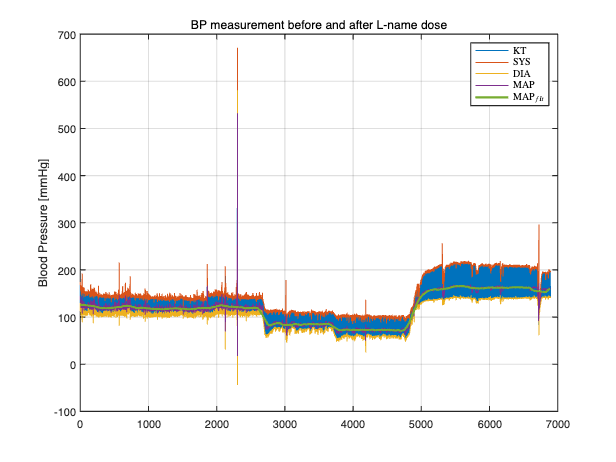

figure(1)
plot(t0(idx_sys), p0_sys)
plot(t0(idx_dia), p0_dia)
plot(t0(idx_sys(1:len)), map)
plot(t0(idx_sys(1:len)), map_filt, 'LineWidth', 2)
legend('KT','SYS','DIA','MAP','MAP$_{filt}$','Interpreter','latex')

### 6. Identify dynamical model of MAP response to dose of L-name

#### Estimate time of dose injection

Find most dominant changepoint in data

idx = findchangepts(map_filt,'MaxNumChanges',1)

idx = 27757

Find start of the response

id = find(diff(map_filt(1:idx))<0,1,'last')

id = 26521

Get response data

map_response = map_filt(id:end)

map_response =    71.3994   71.3994   71.4019   71.4043   71.4077   71.4093   71.4138   71.4145   71.4200   71.4206   71.4233   71.4251   71.4279   71.4288   71.4291   71.4296   71.4312   71.4321   71.4346   71.4349   71.4370   71.4412   71.4442   71.4484   71.4506   71.4554   71.4578   71.4610   71.4642   71.4658   71.4696   71.4715   71.4752   71.4771   71.4794   71.4828   71.4848   71.4884   71.4889   71.4929   71.4943   71.4966   71.4998   71.5009   71.5032   71.5053   71.5084   71.5111   71.5148   71.5192


Mark start of step response 

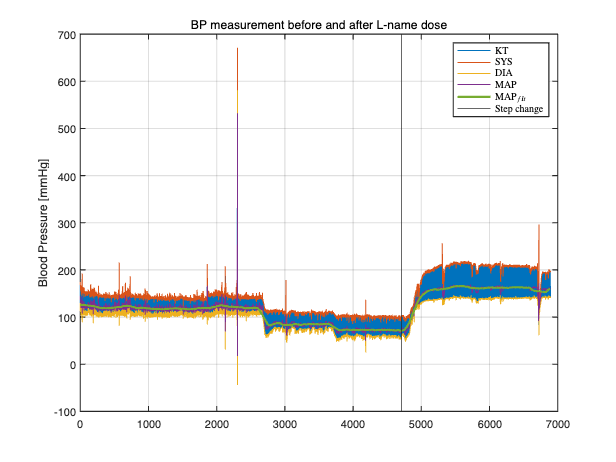

xline(t0(idx_sys(id)),'DisplayName','Step change')

Create input

u = [0 ones(1,length(map_response)-1)];

#### Identify model using RLS method

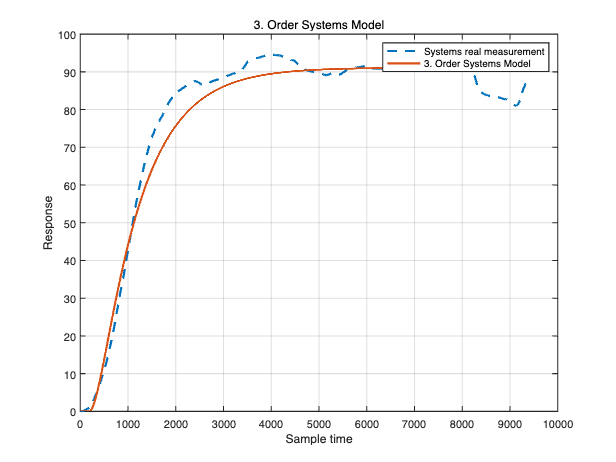

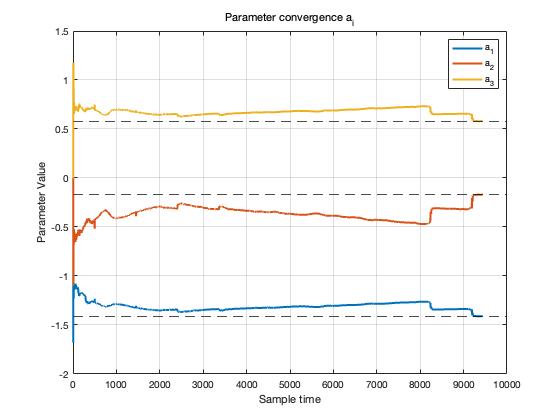

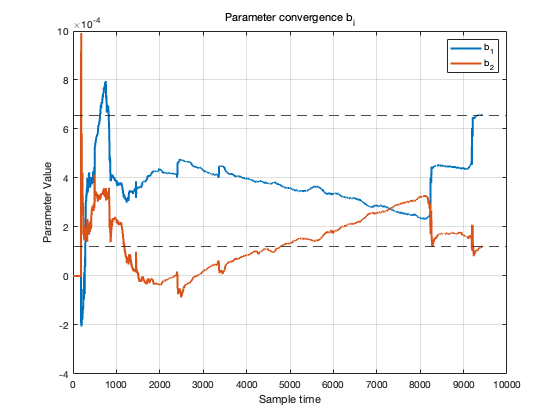

map_res_norm = map_response-map_response(1);
Ts = t0(2)-t0(1);
num_order = 2;
den_order = 3;
idtf = recursiveLeastSquares(u, map_res_norm, Ts, ...
                             num_order, den_order);

idtf.Structure

ans =
 
                    0.0006564 + 0.0001192 z^-1
  z^(-184) * ----------------------------------------
             1 - 1.41 z^-1 - 0.1713 z^-2 + 0.581 z^-3
 
Sample time: 0.0025 seconds
Discrete-time transfer function.



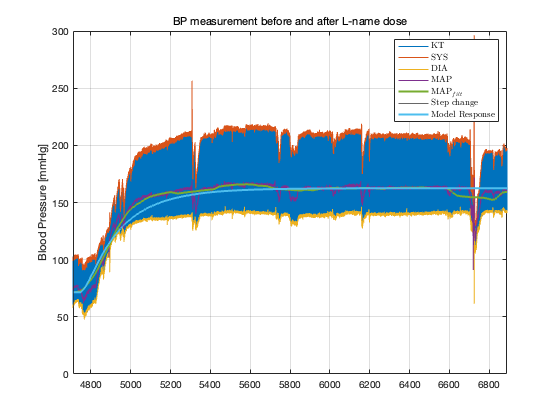

map_sim = lsim(idtf.Structure, u)+map_response(1);
figure(1); plot(t0(idx_sys(id:len)), map_sim, ...
                'LineWidth', 2, ...
                'DisplayName', 'Model Response')
xlim([t0(idx_sys(id)) t0(idx_sys(len))])

### 7. Identify dynamical model of heart rate

len = min([length(hr_min) length(hr_max)])-1000;
hr_mean = mean([hr_max(1:len); hr_min(1:len)]);
hr = movmean(hr_mean(id:end),window);

Plot 

clf(figure(5)); figure(5)
plot(t0(idx_sys(1:len)), hr_mean); hold on
plot(t0(idx_sys(1:len)), movmean(hr_mean,window), 'LineWidth', 2)
grid on
ylabel('Heart Rate [BPM]')
title('HR measurement after L-name dose', ...
      'FontWeight','Normal')
legend('HR','HR$_{filt}$','Interpreter','latex')

Identify model

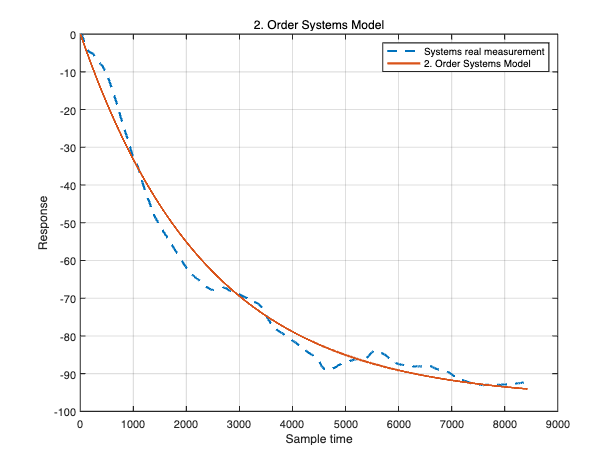

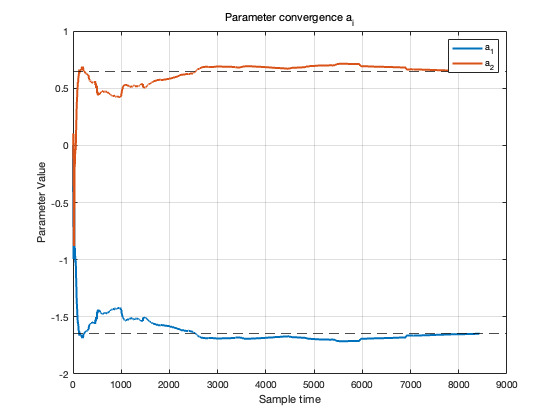

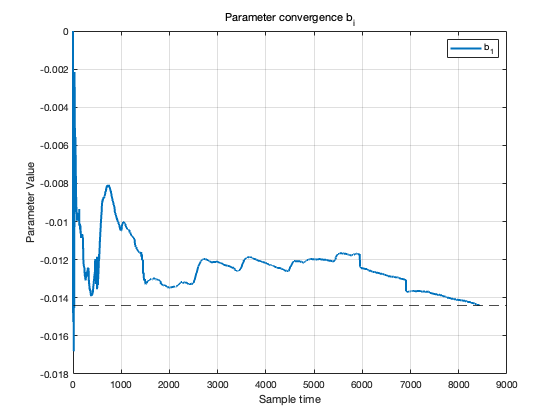

u = [0 ones(1,length(hr)-1)];
hr_norm = hr-hr(1);
Ts = t0(2)-t0(1);
num_order = 1;
den_order = 2;
idtf_hr = recursiveLeastSquares(u, hr_norm, Ts, ...
                             num_order, den_order);

idtf_hr.Structure

ans =
 
            -0.0144
  ----------------------------
  1 - 1.647 z^-1 + 0.6468 z^-2
 
Sample time: 0.0025 seconds
Discrete-time transfer function.



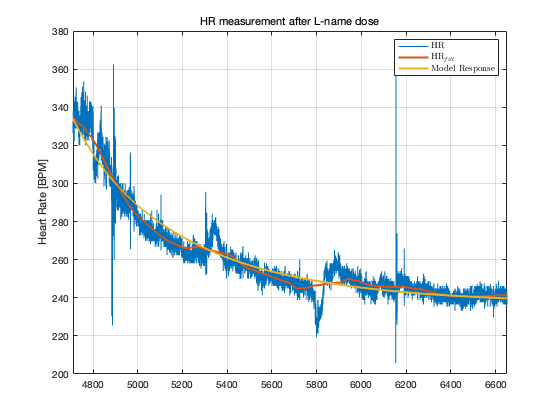

hr_sim = lsim(idtf_hr.Structure, u)+hr(1);
figure(5)
plot(t0(idx_sys(id:len)), hr_sim, ...
     'LineWidth', 2, ...
     'DisplayName', 'Model Response')
xlim([t0(idx_sys(id)) t0(idx_sys(len))])

#### Obj Function

function e = objFcn(x0, p0)
    MPP_max = x0(1);
    MPD_max = x0(2);
    MPP_min = x0(3);
    MPD_min = x0(4);

    [~, idx_max] = findpeaks(p0, ...
                              'MinPeakProminence',MPP_max, ...
                              'MinPeakDistance',MPD_max, ...
                              'Annotate','extents');
    hr_max = movmean(diff(idx_max),20);
    
    [~, idx_min] = findpeaks(-p0, ...
                              'MinPeakProminence',MPP_min, ...
                              'MinPeakDistance',MPD_min, ...
                              'Annotate','extents');
    hr_min = movmean(diff(idx_min),20);
    len = min([length(hr_max) length(hr_min)]);

    e = sum((hr_max(1:len)-hr_min(1:len)).^2); 

end